% Initialization
close all
clear
clc

% Symbolic variables
syms x y real
syms rho mu real positive

% Spatial coordinates
X=[x,y];

% Analytical solution
v=[(y-1)^2*(y+1)^2
   (x-1)^2*(x+1)^2]

$$v = \left[\begin{array}{c} {\left(y-1\right)}^{2}\,{\left(y+1\right)}^{2}\\ {\left(x-1\right)}^{2}\,{\left(x+1\right)}^{2} \end{array}\right]$$

p=(x-1)*(x+1)*(y-1)*(y+1)

$$p = \left(x-1\right)\,\left(x+1\right)\,\left(y-1\right)\,\left(y+1\right)$$

f_v=[rho*(x-1)^2*(x+1)^2*((2*y-2)*(y+1)^2+(2*y+2)*(y-1)^2)-...
     mu*(2*(y-1)^2+2*(y+1)^2+2*(2*y-2)*(2*y+2))+...
     (x+1)*(y-1)*(y+1)+(x-1)*(y-1)*(y+1)
     rho*(y-1)^2*(y+1)^2*((2*x-2)*(x+1)^2+(2*x+2)*(x-1)^2)-...
     mu*(2*(x-1)^2+2*(x+1)^2+2*(2*x-2)*(2*x+2))+...
     (x-1)*(x+1)*(y+1)+(x-1)*(x+1)*(y-1)]

$$f\_v = \left[\begin{array}{c} \left(x-1\right)\,\left(y-1\right)\,\left(y+1\right)-\mu \,\left(2\,{\left(y-1\right)}^{2}+2\,{\left(y+1\right)}^{2}+\left(2\,y+2\right)\,\left(4\,y-4\right)\right)+\left(x+1\right)\,\left(y-1\right)\,\left(y+1\right)+\rho \,{\left(x-1\right)}^{2}\,{\left(x+1\right)}^{2}\,\left(\left(2\,y-2\right)\,{\left(y+1\right)}^{2}+\left(2\,y+2\right)\,{\left(y-1\right)}^{2}\right)\\ \left(x-1\right)\,\left(x+1\right)\,\left(y-1\right)-\mu \,\left(2\,{\left(x-1\right)}^{2}+2\,{\left(x+1\right)}^{2}+\left(2\,x+2\right)\,\left(4\,x-4\right)\right)+\left(x-1\right)\,\left(x+1\right)\,\left(y+1\right)+\rho \,{\left(y-1\right)}^{2}\,{\left(y+1\right)}^{2}\,\left(\left(2\,x-2\right)\,{\left(x+1\right)}^{2}+\left(2\,x+2\right)\,{\left(x-1\right)}^{2}\right) \end{array}\right]$$


% Inertia
I=simplify(rho*mygradient(v,X)*v);

% Velocity gradient
Dv=simplify([diff(v(1),x) diff(v(1),y)
             diff(v(2),x) diff(v(2),y)]);

% Strain rate tensor
epsilon=simplify((Dv+Dv')/2);

% Check residual of velocity
R_v=simplify([I(1)-2*mu*(diff(epsilon(1,1),x)+diff(epsilon(1,2),y))+diff(p,x)-f_v(1)
              I(2)-2*mu*(diff(epsilon(2,1),x)+diff(epsilon(2,2),y))+diff(p,y)-f_v(2)])

$$R\_v = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$


% Check residual of pressure
R_p=simplify(diff(v(1),x)+diff(v(2),y))

$$R\_p = 0$$

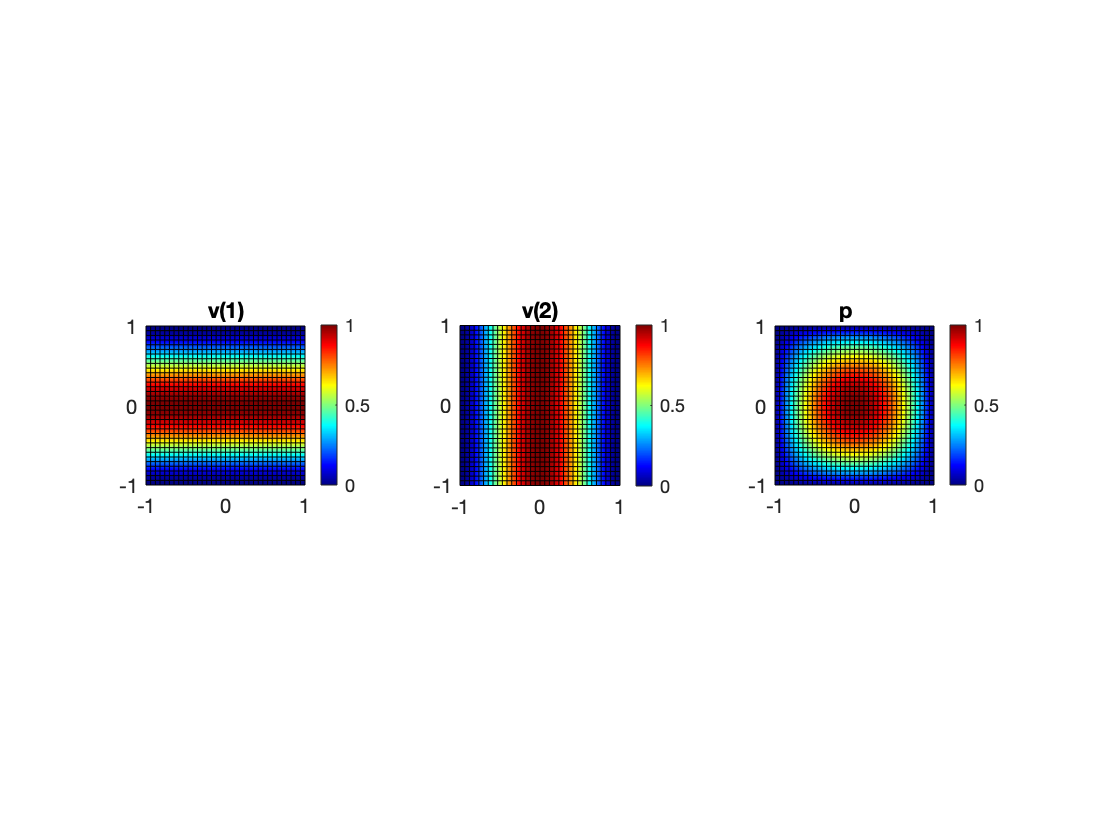


% Numerical values
rho=1; mu=1;

% Plot solution
figure;
subplot(1,3,1); fsurf(@(x,y) eval(v(1)),[-1,+1,-1,+1]); view(2); axis('equal'); colormap('jet'); colorbar; title('v(1)');
subplot(1,3,2); fsurf(@(x,y) eval(v(2)),[-1,+1,-1,+1]); view(2); axis('equal'); colormap('jet'); colorbar; title('v(2)');
subplot(1,3,3); fsurf(@(x,y) eval(p   ),[-1,+1,-1,+1]); view(2); axis('equal'); colormap('jet'); colorbar; title('p   ');

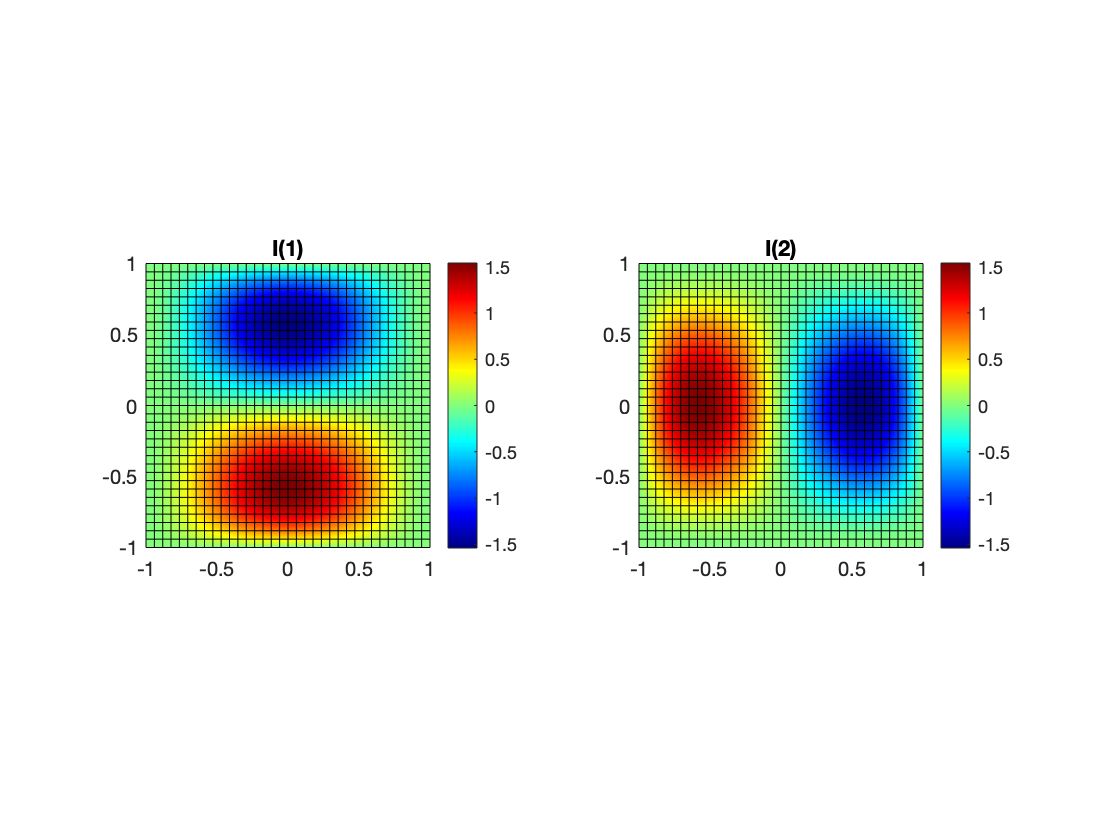

figure;
subplot(1,2,1); fsurf(       eval(I(1)),[-1,+1,-1,+1]); view(2); axis('equal'); colormap('jet'); colorbar; title('I(1)');
subplot(1,2,2); fsurf(       eval(I(2)),[-1,+1,-1,+1]); view(2); axis('equal'); colormap('jet'); colorbar; title('I(2)');